% header

# Runs of random numbers 

To simulate the effect of rare events (e.g., mechanical failures, accidents, above average snow fall), it is sometimes valuable to investigate "runs" of data. In this analysis, we are interested in evaluating how often numbers in a column continuously increase. Consider the data stored in the variable `x`. In the first column, the values 10, 14, and 44 are a run of 3 increasing numbers. In the fifth column the values 8, 14, 15, and 38 (highlighted in red) are a run of 4 increasing numbers. Other examples (highlighted and not highlighted) are shown in the below figure.

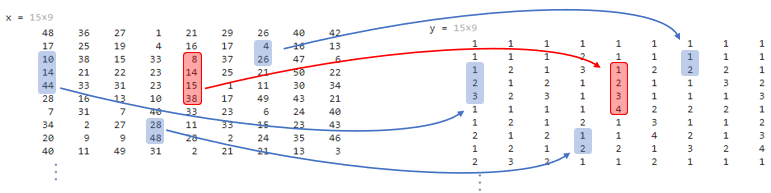

Your task is to write the code that will evaluate the data in the variable `x` and create the corresponding variable `y` which identifies the number of values in a run. Continuing with the red highlighted data, since the 8 is less than 16, the corresponding element for 8 in `y` is 1. Next, 14 is greater than 8, so the corresponding element for 14 in `y` is 2. Next, 15 is greater than 14, so the corresponding element in `y` is 3. Next, 38 is greater than 15, so the corresponding element in `y` is 4. Then, 33 is less than 38 and the corresponding element in `y` is 1.

*Hints:*

- *It will be advantageous to intialize *`y`* as a matrix of ones.*

- *To figure out the value to store in *`y`* when there is an increase, add 1 to the value in the previous row.*

Questions: 

- What is the biggest run?

- How many runs of three exist?

x=randi([1 50] ,[15,9])

x =     10    47    27    10    41     5    22    24    50
    22    24    46    10    45    24     3    32     7
    38    12    28    17    22     1     3    46    12
     2    20    22    45    17    46     5     9     2
    48    36    28    24    30    33    30    36    31
    39    28    36    21    46     1    13    29     6
    28    38     1     9    36     2    43    22    21
    10    50    41    49    19    11    43    45    45
    25    49     8    21    37    23    49    20    28
    26    27    24    43    48     7    25     9    19


y=randi([1] ,[15,9]);
[r,c]=size(x)

r = 15

c = 9

for row=2:r
    for col=1:c
        if x(row,col)>x(row-1,col)
            y(row,col)=y(row-1,col)+1;
        end
    end
end
disp(y)

     1     1     1     1     1     1     1     1     1
     2     1     2     1     2     2     1     2     1
     3     1     1     2     1     1     1     3     2
     1     2     1     3     1     2     2     1     1
     2     3     2     1     2     1     3     2     2
     1     1     3     1     3     1     1     1     1
     1     2     1     1     1     2     2     1     2
     1     3     2     2     1     3     1     2     3
     2     1     1     1     2     4     2     1     1
     3     1     2     2     3     1     1     1     1
     4     2     1     1     1     1     1     2     1
     1     1     2     1     1     2     1     1     2
     2     1     3     2     1     1     2     1     3
     1     2     1     1     1     2     3     2     1
     1     3     2     1     2     1     1     3     2

